# Using Functions and Projectors

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

In this tutorial, we will learn how to use Projectors in Swan.

## Functions in Swan

Swan's `Functions` represent mathematical functions. Firstly, their domain needs to be defined using a `Mesh`:

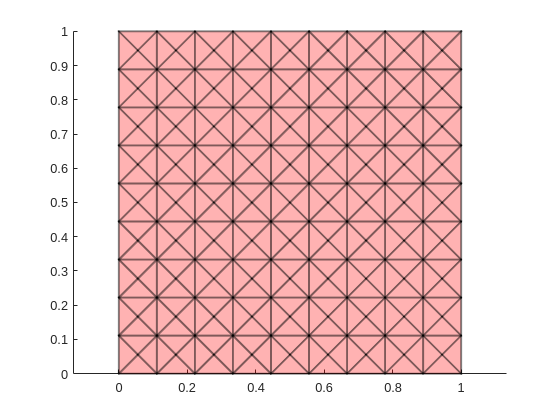

clear;
close all;

x1 = linspace(0,1,10);
x2 = linspace(0,1,10);
[xv,yv] = meshgrid(x1,x2);
[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');
sBg.coord  = V(:,1:2);
sBg.connec = F;
mesh = Mesh.create(sBg);
figure
mesh.plot()

Having created a mesh, we can now dive deeper into the various functions that Swan includes. We can start with AnalyticalFunction, which uses a function handle to determine its value:

sAF.fHandle = @(x) sin(2*pi*x(1,:,:)); % f(x) = sin(2*pi*x)
sAF.ndimf   = 1; % number of dimensions
sAF.mesh    = mesh;
xFun = AnalyticalFunction(sAF);

These functions have additional useful methods:

- `evaluate(xG)`: returns the values of the functions at the given Gauss points

- `plot()`: plot the function in Matlab

- `print(filename, software)`: print the function to visualize it in GiD or Paraview

## Projections in Swan

To project a function into a space *S*, one must find the function of the space *S* such that the norm of the difference between the analytical function and the function of *S* its minimal. In Swan we can project this function onto various different spaces, including P0, P1, P2 and P3 using the function `project`:

p0fun = xFun.project('P0');
p1fun = xFun.project('P1');
p2fun = xFun.project('P2');
p3fun = xFun.project('P3');

The resultant `p0fun`, `p1fun`, `p2fun` and `p3fun` are the projections of `xFun` into the respective spaces. These functions can be evaluated, plotted, or printed like the analytical ones.

## Projected Functions Error

In order to compute the error generated during the projection of the function, we can use the `Integrator` class as it is shown next:

eFun1 = xFun-p1fun;
eFun2 = xFun-p2fun;
eFun3 = xFun-p3fun;

error_P1 = Norm(eFun1,'L2')/Norm(p1fun,'L2');
error_P2 = Norm(eFun2,'L2')/Norm(p2fun,'L2');
error_P3 = Norm(eFun3,'L2')/Norm(p3fun,'L2');

fprintf('Error for the P1 projection: %e\n',error_P1)

Error for the P1 projection: 1.253400e-02


fprintf('Error for the P2 projection: %e\n',error_P2)

Error for the P2 projection: 3.162304e-04


fprintf('Error for the P3 projection: %e\n',error_P3)

Error for the P3 projection: 1.524026e-14


If this process is repeated for different numbers of elements, the error trend can be studied. First define meshes with different number of elements:

N = [8 16 32 64];               % Number of elements by side
m = cell(size(N));              % to store the meshes
for i = 1:length(N)             % Repeat the same process shown before to create meshes
    x1 = linspace(0,1,N(i));
    x2 = linspace(0,1,N(i));
    [xv,yv] = meshgrid(x1,x2);
    [F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');
    sBg.coord  = V(:,1:2);
    sBg.connec = F;
    m{i} = Mesh.create(sBg);   % Store the meshes
end

Now let's repeat the process of projecting the functions and calculating and storing the error for these meshes:

e_p1 = zeros(size(N)); 
e_p2 = zeros(size(N));
e_p3 = zeros(size(N));

for i = 1:length(N)         % Create P1, P2 and P3 functions for every mesh in m
    sAF.mesh = m{i};
    xFun = AnalyticalFunction(sAF);
    
    p1fun = xFun.project('P1');
    p2fun = xFun.project('P2');
    p3fun = xFun.project('P3');
    
    eFun1 = xFun-p1fun;
    eFun2 = xFun-p2fun;
    eFun3 = xFun-p3fun;
    
    e_p1(i) = Norm(eFun1,'L2')/Norm(p1fun,'L2');
    e_p2(i) = Norm(eFun2,'L2')/Norm(p2fun,'L2');
    e_p3(i) = Norm(eFun3,'L2')/Norm(p3fun,'L2');
end

Finally, we can plot the results in order to observe its behaviour:

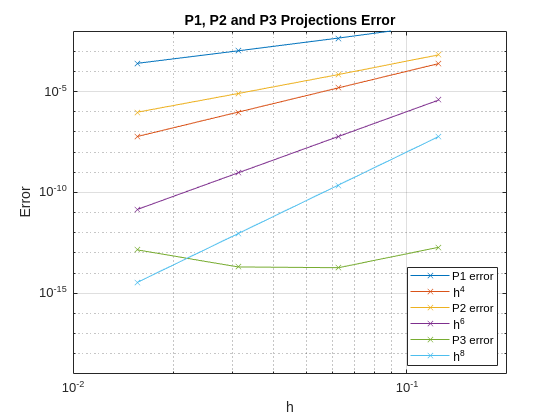

figure()
loglog(1./N,e_p1,'-x')
hold on
loglog(1./N,1./N.^4,'-x')
loglog(1./N,e_p2,'-x')
loglog(1./N,1./N.^6,'-x')
loglog(1./N,e_p3,'-x')
loglog(1./N,1./N.^8,'-x')

grid on
xlim([10e-3 0.2])
ylim([10e-20 10e-3])
legend('P1 error','h^4','P2 error','h^6','P3 error','h^8','Location','best')
xlabel('h')
ylabel('Error')
title('P1, P2 and P3 Projections Error')

As it can be expected, as the degree of the polynomial space increases, the error decreases. This trend is also observated as meshes with more elements are used of elements (lower values of` h=1/N`). The rate of decrease of the error with h also varies with the order of the polynomial projection. With figher orders, the projections get closer in a faster way to the function projected.